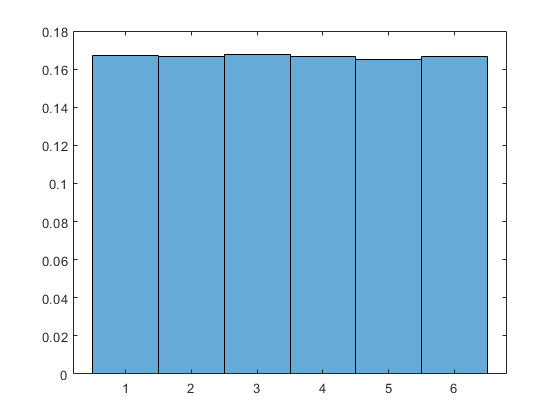

% risultati esperimento lancio di un dado
n = 100000;
result = unidrnd(6,1,n);
histogram(result,'Normalization','probability')

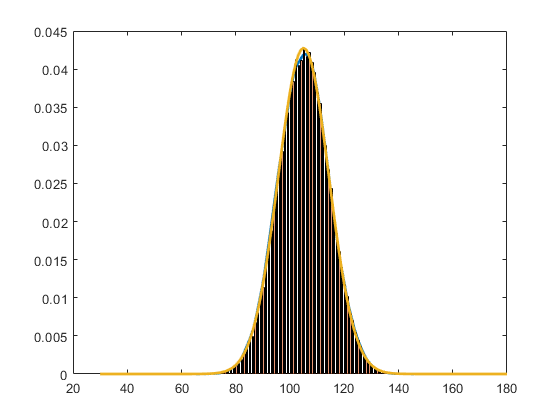

% teorema limite centrale
result = zeros(1,n);
number_of_experiments = 30;
for ii=1:n
    for jj=1:number_of_experiments
        result(ii) = result(ii)+unidrnd(6);
    end  
end
[f,xi] = ksdensity(result);
plot(xi,f,'LineWidth',2)
hold on;
histogram(result,'Normalization','probability')
x = number_of_experiments:1:number_of_experiments*6;
pdf = normpdf(x,mean(result),std(result));
plot(x,pdf,'LineWidth',2)